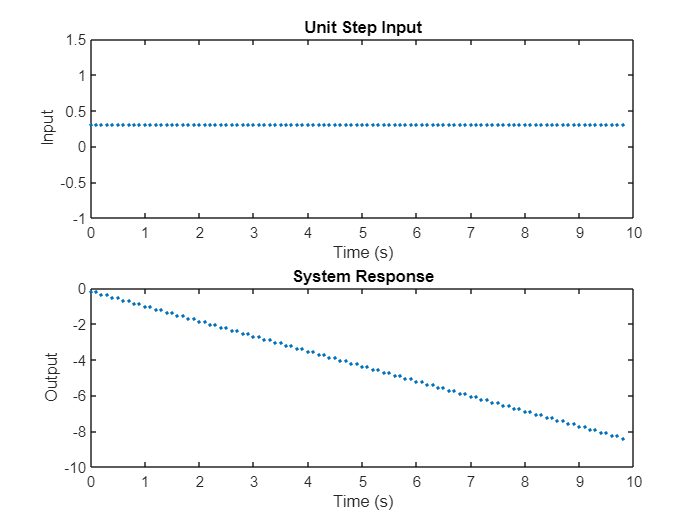

s = tf("s");

PID_s = -22.84 - 2.8088/s - 22.344*s;

Gs = tf(-m*g*d, [L*(J/R^2+m) 0 0]);

% Define the sample time
Ts = .1;
Gz = c2d(Gs, Ts, "tustin");

PID_z = c2d(PID_s, Ts, "tustin");
num = PID_z.Numerator();
num = cell2mat(num);
den = PID_z.Denominator();
den = cell2mat(den);

a1 = -den(2);
a2 = -den(3);
b0 = num(1);
b1 = num(2);
b2 = num(3);

% Define the input signal
N = 10/Ts+1; % Number of samples
u = ones(1,N) * 0.3; % Input signal is a step function value of 0.3

% Implement the difference equation
y = zeros(1,N); % Initialize the output signal
for k = 3:N
    y(k) = a1*y(k-1) + a2*y(k-2) + b0*u(k) + b1*u(k-1) + b2*u(k-2);
end
y = y(3:end); % remove first two elements of y to align with the input signal
u = u(3:end);

% Plot the input and output signals
t = (0:length(u)-1)*Ts; % Time vector

subplot(2,1,1)
plot(t,u, ".")
xlabel('Time (s)')
ylabel('Input')
title('Unit Step Input')

subplot(2,1,2)
plot(t,y, ".")
xlabel('Time (s)')
ylabel('Output')
title('System Response')

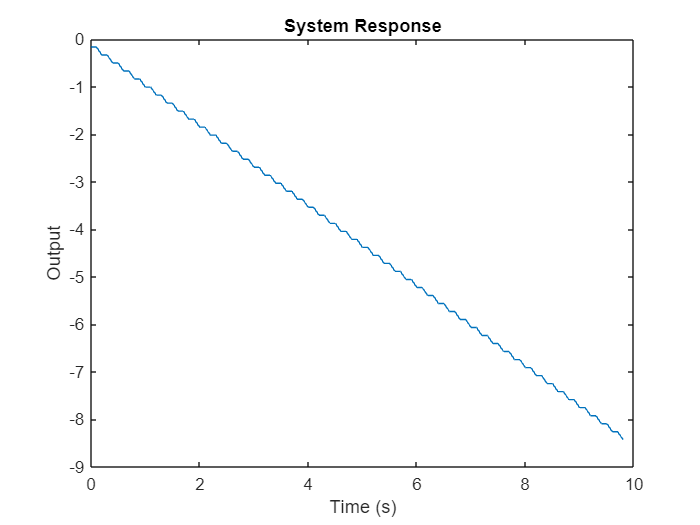



subplot(1,1,1)
plot(t,y)
xlabel('Time (s)')
ylabel('Output')
title('System Response')